## Exercise 1

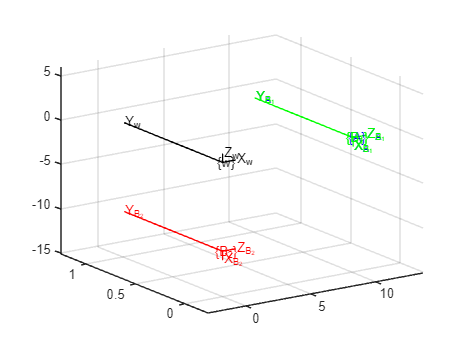

% a
w_T_a = transl(10,0,0) * troty(90,'deg');

%b
w_T_b = transl(10,0,0) * troty(90,'deg');

w_T_b_2 = troty(90, 'deg') * transl(10,0,0);

% To obstain same solution as w_T_a using a premultiplication of a rotation
% matrix:
% w_T_b = troty(90, 'deg') * transl(0,0,-10);


figure(1); clf; grid; hold on;
trplot(eye(4), 'frame', 'w', 'color' ,'k'); trplot(w_T_a, 'frame', 'A'); trplot(w_T_b, 'frame', 'B_1','color' ,'g'); trplot(w_T_b_2, 'frame', 'B_2', 'color' ,'r');

## Exercise 2

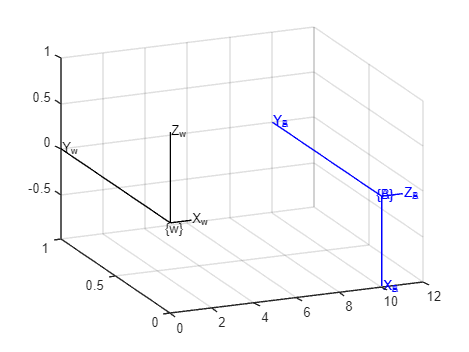

% a
w_T_a = transl(10,0,0) * troty(90, 'deg');
% b
w_T_b = transl(10,0,0) * troty(90, 'deg');
figure(2); clf; grid; hold on;
trplot(eye(4), 'frame', 'w', 'color' ,'k'); trplot(w_T_a, 'frame', 'A'); trplot(w_T_b, 'frame', 'B');

## Exercise 3

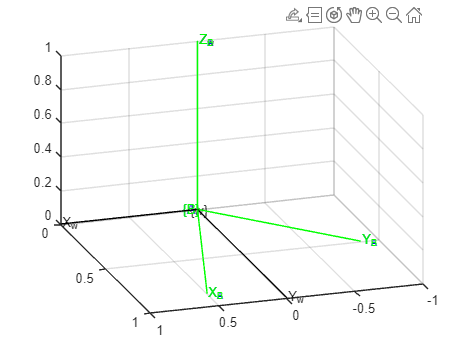

w_T_a = trotz(45 ,'deg') * troty(0,'deg') * trotz(15,'deg');
w_T_b = trotz(60 ,'deg') * troty(0,'deg') * trotz(0,'deg');
figure(3); clf; grid; hold on;
trplot(eye(4), 'frame', 'w', 'color' ,'k'); trplot(w_T_a, 'frame', 'A', 'color', 'b'); trplot(w_T_b, 'frame', 'B', 'color', 'g');

% w_T_a == w_T_b
%sin(a+b) = sin(a)cos(b) + cos(a)sin(b)
%cos(a+b) = cos(a)cos(b) - sin(a)sin(b) ---> a=45, b=15
rpy_a = tr2rpy(w_T_a);
rpy_b = tr2rpy(w_T_b);

## Exercise 4

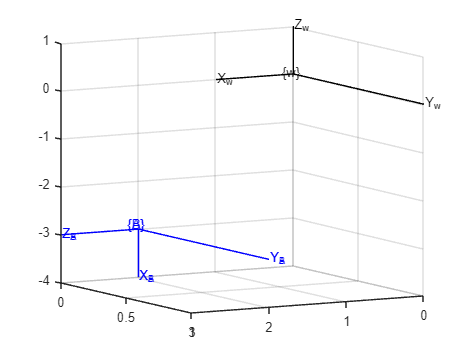

% a
w_T_a = troty(90,'deg') * transl(0,0,2) * transl(3,0,0);
%b
w_T_b = transl(0,0,-3) * transl(2,0,0) * troty(90, 'deg');
figure(4); clf; grid; hold on;
trplot(eye(4), 'frame', 'w', 'color' ,'k'); trplot(w_T_a, 'frame', 'A'); trplot(w_T_b, 'frame', 'B');

## Exercise 5

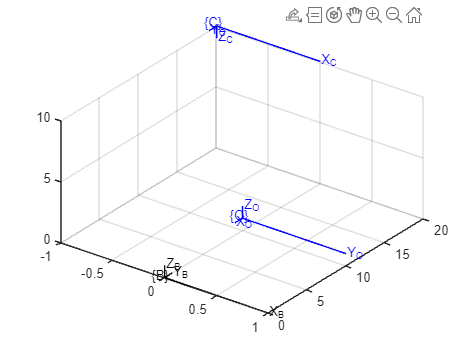

%5.1
c_T_o = [0,1,0,1; 1,0,0,10; 0,0,-1,9; 0,0,0,1];
c_T_b = [1,0,0,1; 0,-1,0,20; 0,0,-1,10 ;0,0,0,1];
b_T_o = inv(c_T_b) * c_T_o;
figure(5); clf; grid; hold on;
trplot(eye(4), 'frame', 'B', 'color' ,'k'); trplot(b_T_o, 'frame', 'O'); trplot(inv(c_T_b), 'frame', 'C');

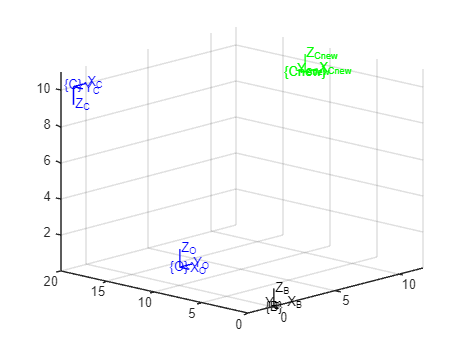

%5.2
new_b_T_c = inv(c_T_b) * trotx(180,'deg') * transl(11,-10,0);
figure(6); clf; grid; hold on;
trplot(eye(4), 'frame', 'B', 'color' ,'k'); trplot(b_T_o, 'frame', 'O'); trplot(inv(c_T_b), 'frame', 'C');trplot(new_b_T_c, 'frame', 'Cnew', 'color','g');

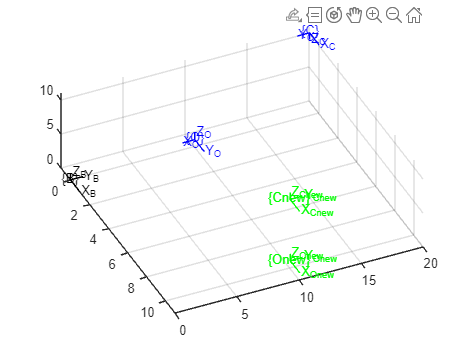

%5.3
new_b_T_o = transl(10,0,0) * b_T_o * trotz(90, 'deg');
new_c_T_o = inv(new_b_T_c) * new_b_T_o;
figure(7); clf; grid; hold on;
trplot(eye(4), 'frame', 'B', 'color' ,'k'); trplot(b_T_o, 'frame', 'O'); trplot(inv(c_T_b), 'frame', 'C');
trplot(new_b_T_o, 'frame', 'Onew', 'color', 'g'); trplot(new_b_T_c, 'frame', 'Cnew', 'color','g');